**STEP 1: LOAD AND VISUALIZE DATA**

% STEP 1: Load and Scroll the Data (for .MAT file)
% Clear workspace and close all figures
clear all;
close all;
clc;
eeglabFolder = 'D:\Neurosience\Signal\eeglab_current\eeglab2026.0.0';
addpath(genpath(eeglabFolder));
% Set the path to your data
data_path = 'D:\Neurosience\Signal\3-Matlab\S1';
file_name = 'Signal department.Matlab in Signal.S1.SampleEEGdata.mat';

% Check if the file exists before loading
full_path = fullfile(data_path, file_name);

if ~exist(full_path, 'file')
    fprintf('File not found: %s\n', full_path);
    fprintf('Searching for alternative files in the directory...\n');
    
    % List all .mat files in the directory
    mat_files = dir(fullfile(data_path, '*.mat'));
    
    if isempty(mat_files)
        error('No .mat files found in the directory: %s\nPlease check the path and try again.', data_path);
    else
        fprintf('Found the following .mat files:\n');
        for i = 1:length(mat_files)
            fprintf('  %d. %s\n', i, mat_files(i).name);
        end
        
        % Ask user to select a file
        fprintf('\nPlease select a file to load:\n');
        for i = 1:length(mat_files)
            fprintf('%d. %s\n', i, mat_files(i).name);
        end
        selection = input('Enter the number of the file to load: ');
        
        if selection >= 1 && selection <= length(mat_files)
            file_name = mat_files(selection).name;
            fprintf('Loading file: %s\n', file_name);
        else
            error('Invalid selection. Please run the script again.');
        end
    end
end

% Load the .mat file
try
    % Load the .mat file
    loaded_data = load(full_path);
    fprintf('File loaded successfully!\n');
    
    % Display the variables in the loaded file
    fprintf('Variables in the .mat file:\n');
    variable_names = fieldnames(loaded_data);
    for i = 1:length(variable_names)
        fprintf('  %d. %s\n', i, variable_names{i});
    end
    
    % Check if the loaded data contains EEG structure
    if isfield(loaded_data, 'EEG')
        EEG = loaded_data.EEG;
        fprintf('Found EEG structure in the .mat file\n');
    elseif isfield(loaded_data, 'eeg')
        EEG = loaded_data.eeg;
        fprintf('Found eeg structure in the .mat file\n');
    else
        % If no EEG structure, try to find the data
        fprintf('No EEG structure found. Checking for data arrays...\n');
        
        % Look for common variable names
        possible_vars = {'data', 'eegdata', 'eeg_data', 'signal', 'EEGdata'};
        found_var = false;
        
        for i = 1:length(possible_vars)
            if isfield(loaded_data, possible_vars{i})
                fprintf('Found data in variable: %s\n', possible_vars{i});
                % Create a basic EEG structure
                EEG.data = loaded_data.(possible_vars{i});
                EEG.nbchan = size(EEG.data, 1);
                EEG.pnts = size(EEG.data, 2);
                EEG.srate = 250; % Default sampling rate, adjust as needed
                EEG.times = (0:EEG.pnts-1) / EEG.srate * 1000; % Time in ms
                EEG.xmin = 0;
                EEG.xmax = (EEG.pnts-1) / EEG.srate;
                EEG.chanlocs = []; % No channel locations
                EEG.event = [];
                found_var = true;
                break;
            end
        end
        
        if ~found_var
            error('Could not find EEG data in the .mat file. Please check the file contents.');
        end
    end
    
catch ME
    fprintf('Error loading file: %s\n', ME.message);
    rethrow(ME);
end

File loaded successfully!


Variables in the .mat file:


  1. EEG


Found EEG structure in the .mat file



% Display basic information about the data
fprintf('\n===== DATA INFORMATION =====\n');


===== DATA INFORMATION =====


fprintf('File name: %s\n', file_name);

File name: Signal department.Matlab in Signal.S1.SampleEEGdata.mat


fprintf('File path: %s\n', data_path);

File path: D:\Neurosience\Signal\3-Matlab\S1


fprintf('Number of channels: %d\n', EEG.nbchan);

Number of channels: 64


fprintf('Number of time points: %d\n', EEG.pnts);

Number of time points: 640


fprintf('Sampling rate: %d Hz\n', EEG.srate);

Sampling rate: 256 Hz


if isfield(EEG, 'times')
    fprintf('Recording duration: %.2f seconds\n', EEG.xmax);
end

Recording duration: 1.50 seconds


if isfield(EEG, 'event') && ~isempty(EEG.event)
    fprintf('Number of events: %d\n', length(EEG.event));
end

Number of events: 311


fprintf('============================\n\n');


% Visualize the raw continuous data
fprintf('Plotting the data for visual inspection...\n');

Plotting the data for visual inspection...


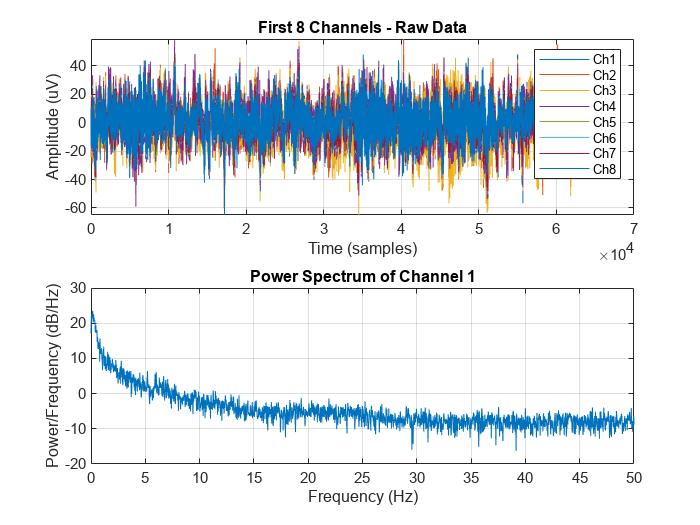


% Plot a quick overview of all channels
figure;
subplot(2,1,1);
plot(EEG.data(1:min(8, EEG.nbchan), :)');
xlabel('Time (samples)');
ylabel('Amplitude (uV)');
title('First 8 Channels - Raw Data');
legend(arrayfun(@(x) sprintf('Ch%d', x), 1:min(8, EEG.nbchan), 'UniformOutput', false));
grid on;

% Plot the power spectrum
subplot(2,1,2);
if isfield(EEG, 'srate')
    [pxx, f] = pwelch(EEG.data(1,:), [], [], [], EEG.srate);
    plot(f, 10*log10(pxx));
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    title('Power Spectrum of Channel 1');
    grid on;
    xlim([0 50]);
end


% If EEGLAB is available, use the scroll plot
try
    pop_eegplot(EEG, 1, 1, 1);
    fprintf('EEGLAB scroll plot opened successfully.\n');
catch
    fprintf('EEGLAB not available. Using basic MATLAB plot.\n');
end

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


EEGLAB scroll plot opened successfully.



fprintf('Data loaded successfully!\n');

Data loaded successfully!


**STEP 2: IDENTIFY AND INTERPOLATE BAD CHANNELS**


% STEP 2: Identify and Interpolate Bad Channels
% First, identify bad channels using statistical criteria
% Using probability criterion (threshold of 4 standard deviations)
EEG = pop_rejchan(EEG, 'elec', [1:EEG.nbchan], 'threshold', 4, 'norm', 'on', 'measure', 'prob');

Computing probability for channels...
4 electrodes labeled for rejection
#	Elec.	Measure
1	Fp1	-0.59
2	AF7	-0.41
3	AF3	-0.20
4	F1	0.40
5	F3	-1.23
6	F5	-1.03
7	F7	-1.36
8	FT7	-2.93
9	FC5	0.96
10	FC3	0.31
11	FC1	0.28
12	C1	0.79
13	C3	0.71
14	C5	-0.32
15	T7	-1.15
16	TP7	-4.90	*Bad*
17	CP5	0.19
18	CP3	0.61
19	CP1	-0.89
20	P1	0.87
21	P3	1.19
22	P5	1.65
23	P7	1.74
24	P9	-8.30	*Bad*
25	PO7	-7.24	*Bad*
26	PO3	1.70
27	O1	0.32
28	Iz	-2.88
29	Oz	0.97
30	POz	2.05
31	Pz	2.02
32	CPz	-1.50
33	Fpz	-1.19
34	Fp2	0.49
35	AF8	0.62
36	AF4	0.42
37	AFz	-2.36
38	Fz	1.48
39	F2	-0.64
40	F4	-0.36
41	F6	-0.78
42	F8	1.31
43	FT8	-0.07
44	FC6	-0.22
45	FC4	-0.60
46	FC2	-0.77
47	FCz	0.37
48	Cz	0.83
49	C2	0.90
50	C4	0.88
51	C6	0.78
52	T8	-0.09
53	TP8	-1.04
54	CP6	-0.17
55	CP4	0.17
56	CP2	1.36
57	P2	1.77
58	P4	0.10
59	P6	1.30
60	P8	0.94
61	P10	-7.32	*Bad*
62	PO8	-1.72
63	PO4	1.83
64	O2	0.37
Removing 4 channel(s)...
eeg_checkset warning: 1/311 events had out-of-bounds latencies and were removed



% Display which channels were marked as bad
fprintf('Bad channels identified and marked\n');

Bad channels identified and marked



% Interpolate the marked bad channels using spherical spline method
EEG = pop_interp(EEG, EEG.chanlocs, 'spherical');

% Visual check after interpolation
pop_eegplot(EEG, 1, 1, 1);

% Save the data after interpolation
EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_interp.set', 'filepath', data_path);

Saving dataset...


fprintf('Data saved after interpolation\n');

Data saved after interpolation


**STEP 3: RE-REFERENCING**

% STEP 3: Re-referencing to Average Reference
% This step re-references the data to the average of all scalp electrodes

% Re-reference to average reference
EEG = pop_reref(EEG, []); % Empty brackets mean average reference

Re-referencing data



% Visual check after re-referencing
pop_eegplot(EEG, 1, 1, 1);

% Save the data after re-referencing
EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_reref.set', 'filepath', data_path);

Saving dataset...


fprintf('Data saved after re-referencing\n');

Data saved after re-referencing


**STEP 4: FILTERING (BEFORE EPOCHING)**

% STEP 4: Filtering the Data
% Apply high-pass and low-pass filters to remove unwanted frequencies

% High-pass filter at 0.5 Hz to remove slow drifts
EEG = pop_eegfiltnew(EEG, 0.5, []);

pop_eegfiltnew() - performing 1691 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): 0.5 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.250059171597633 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% Low-pass filter at 30 Hz to remove high-frequency noise
EEG = pop_eegfiltnew(EEG, [], 30);

pop_eegfiltnew() - performing 115 point lowpass filtering.
pop_eegfiltnew() - transition band width: 7.41052631578947 Hz
pop_eegfiltnew() - passband edge(s): 30 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 33.7052631578947 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% Visual check after filtering
pop_eegplot(EEG, 1, 1, 1);

% Save the data after filtering
EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_filtered.set', 'filepath', data_path);

Saving dataset...


fprintf('Data saved after filtering\n');

Data saved after filtering


**STEP 5: EPOCHING (WITH BASELINE CORRECTION)**

% STEP 5: Epoching (Simplified for numeric events)
epoch_start = -0.2;
epoch_end = 0.8;

% First check what events are available
if ~isempty(EEG.event) && isfield(EEG.event, 'type')
    % Check if event types are numeric
    if isnumeric([EEG.event.type])
        unique_types = unique([EEG.event.type]);
        fprintf('Available numeric event types: ');
        disp(unique_types);
        
        % Use the first event type (or specify which one)
        event_type = unique_types(1); % Change this to your desired event
        fprintf('Epoching around event type: %d\n', event_type);
        
        % Create epochs
        EEG = pop_epoch(EEG, {num2str(event_type)}, [epoch_start epoch_end]);
    else
        % If string types
        unique_types = unique({EEG.event.type});
        fprintf('Available string event types: ');
        disp(unique_types);
        
        % Use the first event type
        event_type = unique_types{1};
        fprintf('Epoching around event type: %s\n', event_type);
        
        % Create epochs
        EEG = pop_epoch(EEG, {event_type}, [epoch_start epoch_end]);
    end
end

Available numeric event types: 

     1     2    31    32    51    52



Epoching around event type: 1


pop_epoch():122 epochs selected
Epoching...


% BASELINE CORRECTION - SIMPLE FIX
% First, check the time range of your data
fprintf('Data time range: %.2f to %.2f ms\n', EEG.xmin*1000, EEG.xmax*1000);

Data time range: -199.22 to 796.88 ms



% Use baseline from beginning of epoch to 0
% This ensures the baseline range is always valid
baseline_start = EEG.xmin * 1000; % Start of epoch in ms
baseline_end = 0; % Time 0 in ms

fprintf('Using baseline range: %.2f to %.2f ms\n', baseline_start, baseline_end);

Using baseline range: -199.22 to 0.00 ms



% Apply baseline correction
try
    EEG = pop_rmbase(EEG, [baseline_start baseline_end]);
    fprintf('Baseline correction successful!\n');
catch
    fprintf('pop_rmbase failed. Trying manual baseline correction...\n');
    
    % Manual baseline correction
    baseline_indices = find(EEG.times >= baseline_start & EEG.times <= baseline_end);
    if ~isempty(baseline_indices)
        baseline_mean = mean(EEG.data(:, baseline_indices, :), 2);
        for trial = 1:EEG.trials
            for ch = 1:EEG.nbchan
                EEG.data(ch, :, trial) = EEG.data(ch, :, trial) - baseline_mean(ch, 1, trial);
            end
        end
        fprintf('Manual baseline correction successful!\n');
    else
        fprintf('Could not perform baseline correction.\n');
    end
end

pop_rmbase(): Removing baseline...


Baseline correction successful!



% Visualize
pop_eegplot(EEG, 1, 1, 1);
fprintf('Epoching completed! Number of epochs: %d\n', EEG.trials);

Epoching completed! Number of epochs: 96


**STEP 6: AUTOMATIC ARTIFACT REJECTION**

% STEP 6A: Automatic Artifact Rejection using Thresholds
% This step rejects epochs that exceed amplitude threshold

% Set rejection criteria
reject_threshold = 100; % Microvolts (µV)
reject_epochs = [];

% Automatically reject epochs with amplitude exceeding threshold
[EEG, reject_epochs] = pop_eegthresh(EEG, 1, [1:EEG.nbchan], ...
    -reject_threshold, reject_threshold, ...
    epoch_start*1000, epoch_end*1000, 0, 0);

60 channel selected
0/96 trials marked for rejection



% Display number of rejected epochs
fprintf('Number of epochs rejected automatically: %d\n', length(reject_epochs));

Number of epochs rejected automatically: 0


fprintf('Remaining good epochs: %d\n', EEG.trials);

Remaining good epochs: 96



% Visual check after automatic rejection
pop_eegplot(EEG, 1, 1, 1);

% Save the data after automatic rejection
EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_auto_reject.set', 'filepath', data_path);

Saving dataset...


fprintf('Data saved after automatic artifact rejection\n');

Data saved after automatic artifact rejection


**STEP 7: ICA-BASED ARTIFACT REMOVAL**

% STEP 7: ICA-Based Artifact Removal (Simple Version)
fprintf('\n===== STEP 7: ICA ARTIFACT REMOVAL =====\n');


===== STEP 7: ICA ARTIFACT REMOVAL =====



% Check data size
fprintf('Data dimensions: %d channels x %d time points x %d trials\n', ...
    EEG.nbchan, EEG.pnts, EEG.trials);

Data dimensions: 60 channels x 256 time points x 96 trials



% Option 1: Try ICA with basic settings
fprintf('\nAttempting ICA decomposition...\n');


Attempting ICA decomposition...



try
    % Simple ICA with extended mode
    EEG = pop_runica(EEG, 'icatype', 'runica', 'extended', 1);
    fprintf('ICA completed successfully!\n');
    ica_worked = true;
    
catch ME
    fprintf('ICA failed: %s\n', ME.message);
    
    % Option 2: Try with fewer iterations
    fprintf('\nTrying with fewer iterations...\n');
    try
        EEG = pop_runica(EEG, 'icatype', 'runica', 'extended', 1, 'maxsteps', 100);
        fprintf('ICA completed with 100 iterations!\n');
        ica_worked = true;
        
    catch ME2
        fprintf('ICA still failed: %s\n', ME2.message);
        
        % Option 3: Try with PCA reduction
        fprintf('\nTrying with PCA dimension reduction...\n');
        try
            % Reduce to 80% of channels
            n_components = round(EEG.nbchan * 0.8);
            fprintf('Using %d components\n', n_components);
            
            EEG = pop_runica(EEG, 'icatype', 'runica', 'extended', 1, ...
                'pca', n_components, 'maxsteps', 100);
            fprintf('ICA with PCA completed!\n');
            ica_worked = true;
            
        catch ME3
            fprintf('All ICA attempts failed.\n');
            fprintf('Error: %s\n', ME3.message);
            ica_worked = false;
        end
    end
end

Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (59) is smaller than the number of channels (60).

Input data size [59,24576] = 59 channels, 24576 frames/nAfter PCA dimension reduction,
  finding 59 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 7 frames per ICA weight ((3481)^2 = 24576 weights, Initial learning rate will be 0.001, block size 51.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -45.0698 to 34.3679
Reducing the data to 59 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 -

ICA completed successfully!



% If ICA worked, proceed with component inspection
if ica_worked
    fprintf('\n===== ICA COMPONENT INSPECTION =====\n');
    fprintf('Number of components: %d\n', EEG.nbchan);
    
    % Plot component topographies
    figure('Name', 'ICA Components', 'NumberTitle', 'off');
    n_plots = min(16, EEG.nbchan);
    n_cols = 4;
    n_rows = ceil(n_plots / n_cols);
    
    for comp = 1:n_plots
        subplot(n_rows, n_cols, comp);
        try
            topoplot(EEG.icawinv(:, comp), EEG.chanlocs, 'electrodes', 'off');
            title(sprintf('Comp %d', comp));
        catch
            % If topoplot fails, plot the component weights
            plot(EEG.icawinv(:, comp));
            title(sprintf('Comp %d', comp));
            grid on;
        end
    end
    
    % Show component activations
    figure('Name', 'Component Activations', 'NumberTitle', 'off');
    for comp = 1:min(8, EEG.nbchan)
        subplot(2, 4, comp);
        plot(squeeze(EEG.icaact(comp, :, 1)));
        title(sprintf('Component %d - Trial 1', comp));
        grid on;
    end
    
    % Open ICA GUI for manual artifact removal
    fprintf('\nOpening ICA GUI for artifact component removal...\n');
    fprintf('Common artifact components:\n');
    fprintf('  - Blinks: Frontal, sharp peaks\n');
    fprintf('  - Horizontal eye movements: Frontal, bilateral\n');
    fprintf('  - Muscle: High frequency, diffuse\n');
    fprintf('  - Line noise: 50/60 Hz, posterior\n\n');
    
    try
        pop_icagui(EEG);
        fprintf('ICA GUI opened. Select artifact components and press "OK" to remove.\n');
        fprintf('Press any key after closing ICA GUI...\n');
        pause;
    catch
        fprintf('Could not open ICA GUI. Manual component removal required.\n');
        fprintf('To remove components manually, use: pop_icagui(EEG)\n');
    end
    
else
    % If ICA completely failed
    fprintf('\n===== ICA FAILED - USING ALTERNATIVES =====\n');
    fprintf('ICA could not be computed. Using automatic rejection only.\n');
    fprintf('You can try ICA later with different settings.\n');
    fprintf('To run ICA manually: pop_runica(EEG, ''icatype'', ''runica'')\n');
end


===== ICA COMPONENT INSPECTION =====


Number of components: 60



Opening ICA GUI for artifact component removal...


Common artifact components:


  - Blinks: Frontal, sharp peaks


  - Horizontal eye movements: Frontal, bilateral


  - Muscle: High frequency, diffuse


  - Line noise: 50/60 Hz, posterior



Could not open ICA GUI. Manual component removal required.


To remove components manually, use: pop_icagui(EEG)



% Visual check after ICA
fprintf('\nOpening data for final visual inspection...\n');


Opening data for final visual inspection...


pop_eegplot(EEG, 1, 1, 1);

% Save data
try
    EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_after_ICA.set', 'filepath', data_path);
    fprintf('Data saved after ICA processing.\n');
catch
    fprintf('Could not save as .set file. Saving as .mat...\n');
    save(fullfile(data_path, 'sampleEEGdata_after_ICA.mat'), 'EEG');
    fprintf('Data saved as .mat file.\n');
end

Saving dataset...


Data saved after ICA processing.



fprintf('\nStep 7 completed!\n');


Step 7 completed!


**STEP 8: FINAL DATA QUALITY CHECK**

% STEP 8: Final Data Quality Check (Simple Version)
fprintf('\n===== STEP 8: FINAL DATA QUALITY CHECK =====\n');


===== STEP 8: FINAL DATA QUALITY CHECK =====



% Display summary information
fprintf('\n----- DATA SUMMARY -----\n');


----- DATA SUMMARY -----


fprintf('Number of channels: %d\n', EEG.nbchan);

Number of channels: 60


fprintf('Number of epochs: %d\n', EEG.trials);

Number of epochs: 96


fprintf('Time points per epoch: %d\n', EEG.pnts);

Time points per epoch: 256


fprintf('Sampling rate: %d Hz\n', EEG.srate);

Sampling rate: 256 Hz


fprintf('Epoch duration: %.2f seconds\n', EEG.xmax - EEG.xmin);

Epoch duration: 1.00 seconds


fprintf('------------------------\n\n');

------------------------




% Plot 1: Average ERP for all channels
fprintf('Plotting average ERP...\n');

Plotting average ERP...


figure('Name', 'Average ERP - All Channels', 'NumberTitle', 'off');

% Compute average across trials
avg_data = mean(EEG.data, 3);

% Plot first 8 channels
n_plot = min(8, EEG.nbchan);
for ch = 1:n_plot
    subplot(2, 4, ch);
    plot(EEG.times, avg_data(ch, :), 'LineWidth', 1.5);
    xlabel('Time (ms)');
    ylabel('Amplitude (uV)');
    title(sprintf('Channel %d', ch));
    grid on;
    xlim([EEG.times(1) EEG.times(end)]);
end
sgtitle('Average ERP - First 8 Channels');

% Plot 2: Power spectrum
fprintf('Plotting power spectrum...\n');

Plotting power spectrum...


figure('Name', 'Power Spectrum', 'NumberTitle', 'off');

for ch = 1:min(4, EEG.nbchan)
    subplot(2, 2, ch);
    [pxx, f] = pwelch(EEG.data(ch, :, 1), [], [], [], EEG.srate);
    plot(f, 10*log10(pxx), 'LineWidth', 1.5);
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    title(sprintf('Channel %d - Trial 1', ch));
    grid on;
    xlim([0 50]);
end
sgtitle('Power Spectrum - First 4 Channels');

% Plot 3: Check all trials for one channel
fprintf('Plotting all trials for Channel 1...\n');

Plotting all trials for Channel 1...


figure('Name', 'All Trials - Channel 1', 'NumberTitle', 'off');

hold on;
for trial = 1:min(20, EEG.trials)
    plot(EEG.times, EEG.data(1, :, trial), 'Color', [0.5 0.5 0.5 0.3]);
end
plot(EEG.times, mean(EEG.data(1, :, :), 3), 'r', 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Amplitude (uV)');
title('All Trials (gray) and Average (red) - Channel 1');
grid on;
hold off;

% Plot 4: Check for artifacts (amplitude distribution)
fprintf('Plotting amplitude distribution...\n');

Plotting amplitude distribution...


figure('Name', 'Amplitude Distribution', 'NumberTitle', 'off');

% Flatten data for histogram
all_data = EEG.data(:);
histogram(all_data, 50, 'Normalization', 'probability');
xlabel('Amplitude (uV)');
ylabel('Probability');
title('Amplitude Distribution of All Data');
grid on;

% Check for outliers
threshold = 100; % uV
outliers = sum(abs(all_data) > threshold);
fprintf('Number of samples > %d uV: %d (%.2f%%)\n', threshold, outliers, 100*outliers/length(all_data));

Number of samples > 100 uV: 0 (0.00%)



% Display trial rejection info
if exist('reject_epochs', 'var')
    fprintf('\n----- TRIAL REJECTION SUMMARY -----\n');
    fprintf('Number of rejected epochs: %d\n', length(reject_epochs));
    fprintf('Remaining good epochs: %d\n', EEG.trials);
    fprintf('Rejection rate: %.2f%%\n', 100*length(reject_epochs)/(length(reject_epochs)+EEG.trials));
    fprintf('------------------------------------\n');
end


----- TRIAL REJECTION SUMMARY -----


Number of rejected epochs: 0


Remaining good epochs: 96


Rejection rate: 0.00%


------------------------------------



% Open EEGLAB for visual inspection
fprintf('\nOpening EEGLAB scroll plot for final inspection...\n');


Opening EEGLAB scroll plot for final inspection...


try
    pop_eegplot(EEG, 1, 1, 1);
catch
    fprintf('EEGLAB scroll plot not available.\n');
end

% Save final data
fprintf('\nSaving final preprocessed data...\n');


Saving final preprocessed data...


try
    EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_final.set', 'filepath', data_path);
    fprintf('Data saved as .set file.\n');
catch
    save(fullfile(data_path, 'sampleEEGdata_final.mat'), 'EEG');
    fprintf('Data saved as .mat file.\n');
end

Saving dataset...


Data saved as .set file.



% Print completion message
fprintf('\n====================================\n');

fprintf('PREPROCESSING PIPELINE COMPLETED!\n');

PREPROCESSING PIPELINE COMPLETED!


fprintf('Final data saved in: %s\n', data_path);

Final data saved in: D:\Neurosience\Signal\3-Matlab\S1


fprintf('====================================\n\n');


fprintf('Step 8 completed successfully!\n');

Step 8 completed successfully!


**COMPLETE PIPELINE SCRIPT (ALL STEPS TOGETHER)**

% PREPROCESSING - ULTRA SIMPLE VERSION
clear all; close all; clc;

% Load
data_path = 'D:\Neurosience\Signal\3-Matlab\S1';
file_name = 'Signal department.Matlab in Signal.S1.SampleEEGdata.mat';
temp = load(fullfile(data_path, file_name));
EEG = temp.EEG;

% Check event type
if ~isempty(EEG.event) && isfield(EEG.event, 'type')
    if isnumeric(EEG.event(1).type)
        event_val = EEG.event(1).type;
        fprintf('Using numeric event: %d\n', event_val);
        EEG = pop_epoch(EEG, {num2str(event_val)}, [-0.2 0.8]);
    else
        event_val = EEG.event(1).type;
        fprintf('Using string event: %s\n', event_val);
        EEG = pop_epoch(EEG, {event_val}, [-0.2 0.8]);
    end
end

Using numeric event: 2


pop_epoch():38 epochs selected
Epoching...


% Baseline correction 
try
    % Try with original range
    EEG = pop_rmbase(EEG, [-200 0]);
catch
    % If fails, use data range
    fprintf('pop_rmbase failed. Using data range...\n');
    try
        EEG = pop_rmbase(EEG, [EEG.times(1) 0]);
    catch
        % If still fails, do manual
        fprintf('Using manual baseline correction...\n');
        idx = find(EEG.times >= EEG.times(1) & EEG.times <= 0);
        if ~isempty(idx)
            for trial = 1:EEG.trials
                for ch = 1:EEG.nbchan
                    EEG.data(ch, :, trial) = EEG.data(ch, :, trial) - mean(EEG.data(ch, idx, trial));
                end
            end
        end
    end
end

pop_rmbase failed. Using data range...


pop_rmbase(): Removing baseline...



% Filter
EEG = pop_eegfiltnew(EEG, 0.5, 30);

pop_eegfiltnew() - performing 1691 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): [0.5 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.250059171597633 30.2499408284024] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% Re-reference
EEG = pop_reref(EEG, []);

Re-referencing data



% Auto reject
[EEG, rej] = pop_eegthresh(EEG, 1, [1:EEG.nbchan], -100, 100, -200, 800, 0, 0);

64 channel selected
0/10 trials marked for rejection



% ICA (try)
try
    EEG = pop_runica(EEG, 'icatype', 'runica', 'extended', 1);
catch
    fprintf('ICA skipped.\n');
end

Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (62) is smaller than the number of channels (64).

Input data size [62,2560] = 62 channels, 2560 frames/nAfter PCA dimension reduction,
  finding 62 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 2560 data points.
Decomposing 0 frames per ICA weight ((3844)^2 = 2560 weights, Initial learning rate will be 0.001, block size 40.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -26.2867 to 28.0725
Reducing the data to 62 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lr


% Save
EEG = pop_saveset(EEG, 'filename', 'sampleEEGdata_clean.set', 'filepath', data_path);

Saving dataset...


fprintf('Done!\n');

Done!
